# Problem set #2

Problem 1: Evaluation of a known integral using various quadratures: In this problem we are going to compute the price of a European call option with 3 month expiry, strike 12, and implied vol 20, Assume the underlying is 10 now and the interest rate is 4%.

s0 = 10; r = 0.04; k = 12; sigma = 0.2; T = 3/12;

1. Use Black-Scholes formula to compute the price of the call analytically.

d1 = (log(s0 / k) + (r + 0.5 * sigma ^ 2) * T) / (sigma * sqrt(T));
d2 = (log(s0 / k) + (r - 0.5 * sigma ^ 2) * T) / (sigma * sqrt(T));
prc_bs = normcdf(d1) * s0 - normcdf(d2) * discount(r, T, k) % price under BS

prc_bs = 0.0188

2. Calculate the price of the call numerically using the following 3 quadrature methods:

with the number of nodes N = 5, 10, 50, 100 and compute the calculation error as a function of N for each of the methods.

    Under the framework of BS, the dynamics of underlying asset can be expressed in SDE:


$$dS_t =rS_t \textrm{dt}+\sigma S_t dW_t$$


    Which can be solved as:

 $S_t =S_0 e^{\left(r-\frac{1}{2}\sigma^2 \right)\mathrm{dt}+\sigma W_t }$,  $W_t$~ N(0,t).

    The price of call option with strike price k, maturity T, can be expressed as:

    
$$c=E_Q \left\lbrack e^{-\mathrm{rT}} {\left(S_T -k\right)}_+ \right\rbrack =e^{-\mathrm{rT}} \int {\left(S_T -k\right)}_+ \mathrm{dQ}=e^{-\mathrm{rT}} \int_{-d_2 }^{+\infty } \left(S_0 e^{\left(r-\frac{1}{2}\sigma^2 \right)T+\sigma \sqrt{T}x} -k\right)\frac{1}{\sqrt{2\pi }}e^{-\frac{1}{2}x^2 } \mathrm{dx}$$


    where $d_2 =\frac{\mathrm{ln}\frac{S_0 }{k}+\left(r-\frac{1}{2}\sigma^2 \right)T}{\sigma \sqrt{T}}$  

    Consider the integral:

    
$$\int_a^b f\left(x|S_0 ,r,\sigma ,T,k\right)\mathrm{dx}\;=\int_{-d_2 }^{+\infty } \left(S_0 e^{\left(r-\frac{1}{2}\sigma^2 \right)T+\sigma \sqrt{T}x} -k\right)\frac{1}{\sqrt{2\pi }}e^{-\frac{1}{2}x^2 } \textrm{dx}$$


    where a = $-d_2$. Assume b = 10, large enough to illustrate the idea.

a = -(log(s0/k)+(r-0.5*sigma^2)*T)/(sigma*sqrt(T));
b = 10;
f = @(x, s0, r, sigma, T, k) (s0*exp((r-0.5*sigma^2)*T + sigma * sqrt(T).*x) - k).*...
    (1/sqrt(2*pi)).*exp(-0.5*x.^2);
N = [5, 10, 50, 100];

(a) Left Riemann rule    

    If the weight wi = (b − a)/N for all i and the node xi = a + (b − a)*(i − 1)/N, i = 1, ... , N. Then the approximation is the left Riemann sum.

pred_a = zeros(1,length(N));
for i = 1:length(N)
n = N(i);
wi = (b-a)/n;
xi = a + (b-a)*(linspace(1,n,n)-1)/n;
pred_a(i) = sum(wi * f(xi, s0, r, sigma, T, k));
end
pred_a % estimation of integral

pred_a =     0.0041    0.0138    0.0188    0.0189


err_a = abs(prc_bs-pred_a) % calculation error w.r.t price under BS

err_a =     0.0147    0.0050    0.0000    0.0001


(b) Midpoint rule 

    If the weight wi = (b − a)/N for all i and the node xi = a + (b − a)*(i − 1)/N + $\epsilon$*(b-a)/N, i = 1, ... , N. Then the approximation is the midpoint Riemann sum.

epsilon = 0.5;
pred_b = zeros(1,length(N));
for i = 1:length(N)
    n = N(i);
    wi = (b-a)/n;
    xi = a + (b-a)*(linspace(1,n,n)-1)/n + epsilon*(b-a)/n;
    pred_b(i) = sum(wi * f(xi, s0, r, sigma, T, k));
end
pred_b % estimation of integral

pred_b =     0.0235    0.0214    0.0191    0.0190


err_b = abs(prc_bs-pred_b) % calculation error w.r.t price under BS

err_b =     0.0047    0.0026    0.0003    0.0002


(c) Gauss nodes of your choice (say explicitly why you made that choice) 

pred_c = zeros(1,length(N));
for i = 1:length(N)
    n = N(i);
    [xi, wi] = lgwt(n, a, b);
    pred_c(i) = sum(wi.*f(xi,s0, r, sigma, T, k));
end
pred_c % estimation of integral

pred_c =     0.0202    0.0190    0.0190    0.0190


err_c = abs(prc_bs-pred_c) % calculation error w.r.t price under BS

err_c =     0.0014    0.0002    0.0002    0.0002


3. Estimate the experimental rate of convergence of each method and compare it with the known theoretical estimate.

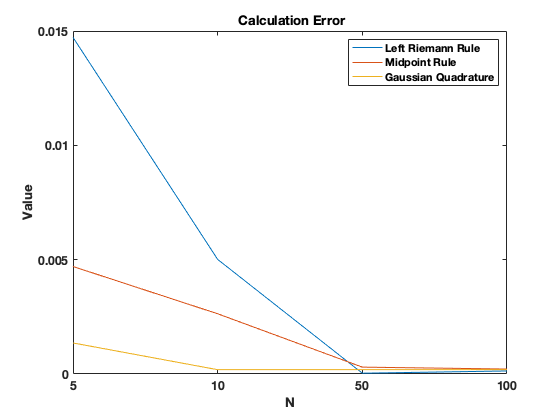

plot1([err_a', err_b', err_c']) 

4. Which method is your favorite and why?

    My favorite method is Gaussian quadrature because it converges to the true value faster than others.

clear;clc;

Problem 2: Calculation of Contingent Options: Let S1 be a random variable that takes on the value of SPY one year from now and let S2 take on the values of SPY 6 months from now. Assume that they are jointly normally distributed with

sigma1 = 20; sigma2 = 15; rho = 0.95; r = 0;
s0 = 270.06; % from yahoo finance 

1. Evaluate the price of the one year call on SPY with the strike K1 = 260. This is an example of a vanilla option.


$$c=E_Q \left\lbrack e^{-\textrm{rT}} {\left(S_1 -k_1 \right)}_+ \right\rbrack =e^{-\textrm{rT}} \int_{k_1 }^{+\infty } \left(x-k_1 \right)\frac{1}{\sqrt{2\pi }\sigma_1 }e^{-\frac{1}{2\sigma_1^2 }{\left(x-\mathrm{s0}\right)}^2 } \textrm{dx}$$


k1 = 260; T1 = 1;
f1 = @(x) (x-k1)./(sqrt(2*pi)*sigma1).*exp(-(x-s0).^2./(2*sigma1^2));
c1 = exp(-r*T1)*integral(f1,k1,1000) % price of option

c1 = 13.9975

2. Evaluate the price of the one year call on SPY with the strike K1 = 260, contingent on SPY at 6 months being below 250. This is a contingent option.


$$c=E_Q \left\lbrack e^{-\textrm{rT}} {\left(S_1 -k_1 \right)}_+ 1_{S_2 <250} \right\rbrack =e^{-\textrm{rT}} \int_{-\infty }^{250} \int_{k_1 }^{+\infty } \left(x-k_1 \right)\textrm{p}\left(x,y\right)\textrm{dxdy}$$


mu1 = s0;
mu2 = s0;
f2 = @(x1,x2) (x1-k1).*1./(2*pi*sigma1*sigma2*sqrt(1-rho^2)).*...
exp(((x1-mu1).^2/sigma1^2 - 2*rho*(x1-mu1).*(x2-mu2)/sigma1/sigma2 +...
(x2-mu2).^2/sigma2^2)/(-2*(1-rho^2)));
c2 = exp(-r*T1)*integral2(f2,k1,1000,0,250) % price of option

c2 = 2.0393e-04

3. Calculate the contingent option again, but with ρ = 0.8, ρ = 0.5, and ρ = 0.2.

rho_list = [0.8;0.5;0.2];
c3 = zeros(1, length(rho_list));
for i = 1:length(rho_list)
    rho = rho_list(i);
    f2 = @(x1,x2) (x1-k1).*1./(2*pi*sigma1*sigma2*sqrt(1-rho^2)).*...
    exp(((x1-mu1).^2/sigma1^2 - 2*rho*(x1-mu1).*(x2-mu2)/sigma1/sigma2 + ...
    (x2-mu2).^2/sigma2^2)/(-2*(1-rho^2)));
    c3(i) = exp(-r*T1)*integral2(f2,k1,1000,0,250);
end
c3 % price of option

c3 =     0.0420    0.3448    0.8471


4. Does dependence on ρ make sense?

    Yes. When rho is large, and given that 6-month price plummeted, there is little chance for 1-year price to be greater than k1, because of the huge positive correlation between them. On the contrary, if rho is small, the chance would be larger.

5. Calculate the contingent option again, but with SPY at 6 months below 240, 230, and 220.

s2_list = [240;230;220]; rho = 0.95;
c5 = zeros(1, length(s2_list));
for i = 1:length(s2_list)
    f2 = @(x1,x2) (x1-k1).*1./(2*pi*sigma1*sigma2*sqrt(1-rho^2)).*...
    exp(((x1-mu1).^2/sigma1^2 - 2*rho*(x1-mu1).*(x2-mu2)/sigma1/sigma2 +...
    (x2-mu2).^2/sigma2^2)/(-2*(1-rho^2)));
    c5(i) = exp(-r*T1)*integral2(f2,k1,1000,0,s2_list(i));
end
c5

c5 = 	1.0e+-7 *

    0.1428    0.0000    0.0000


6. Does the dependence on the 6 month value make sense?

    Yes, When rho is fixed at 0.95, if 6-month price plummeted more heavily, there is little chance for 1-year price to be greater than k1.

7. Under what conditions do you think the price of the contingent option will equal the price of the vanilla one?

    If we change the contigent condition to one trivial criterion, ex. "contingent on SPY at 6 months being below 1000." the price of the contingent option will equal the price of the vanilla one, because this condition would hold without doubt.